# SMP L7 - Efterår 2015 assignment 2

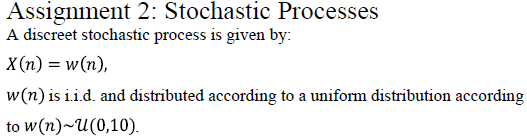

The matlab function unifrnd can be used to generate continuous uniform random numbers.

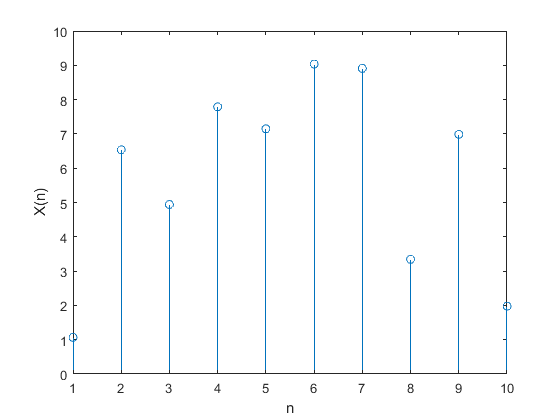

a = 0; % lower
b = 10; % upper
X = unifrnd(a,b,1,10);

stem(X)
xlabel('n')
ylabel('X(n)')

To generate randomly distributed values, we can use the rand() function.

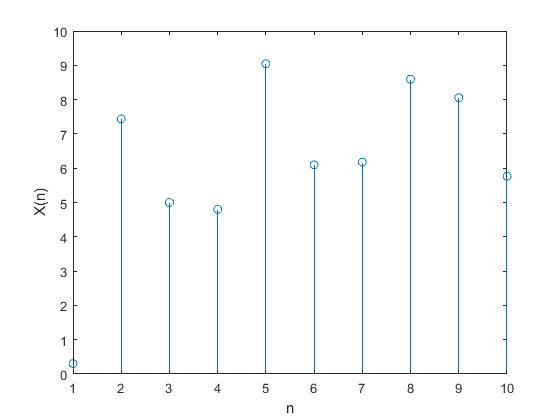

b = 10; % upper
a = 0; % lower
n = 10; % number of samples
X = 10*rand([1,n]);
stem(X)
xlabel('n')
ylabel('X(n)')

The ensemble mean can be calculated by looking at the formula book, p. 54 for continuous uniform distributions:


$$E\left\lbrack X\right\rbrack =\frac{a+b}{2}=\frac{0+10}{2}=5$$


ensemble_mean = 5;

The ensemble variance can be calculated by using the formula in the book, p. 54:


$$\mathrm{Var}\left(X\right)=\frac{{\left(b-a\right)}^2 }{12}=\frac{{\left(10-0\right)}^2 }{12}=\frac{100}{12}=\frac{25}{3}=8\ldotp 33$$


ensemble_var = 25/3;

The autocorrelation is defined by: $R_{\mathrm{XX}} \left(\tau \;\right)=E\left\lbrack X\left(t\right)X\left(t+\tau \;\right)\right\rbrack$


$$R_{\mathrm{XX}} \left(0\right)=E\left\lbrack w\left(n\right)\cdot \;w\left(n\right)\right\rbrack =\mathrm{Var}\left(w\left(n\right)\right)+E{\left\lbrack w\left(n\right)\right\rbrack }^2$$


rxx0 = ensemble_var + ensemble_mean^2

rxx0 = 33.3333

$R_{\mathrm{XX}} \left(1\right)=E\left\lbrack w\left(n\right)\cdot \;w\left(n+1\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack \cdot E\left\lbrack w\left(n+1\right)\right\rbrack$    We can do the last trick, since w(n) and w(n+1) are i.i.d.

rxx1 = ensemble_mean^2

rxx1 = 25


$$R_{\mathrm{XX}} \left(2\right)=E\left\lbrack w\left(n\right)\cdot \;w\left(n+2\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack \cdot E\left\lbrack w\left(n+2\right)\right\rbrack$$


rxx2 = ensemble_mean^2

rxx2 = 25


$$R_{\mathrm{XX}} \left(3\right)=E\left\lbrack w\left(n\right)\cdot \;w\left(n+3\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack \cdot E\left\lbrack w\left(n+3\right)\right\rbrack$$


rxx3 = ensemble_mean^2

rxx3 = 25

The process is WSS since the ensemble mean and variance are independent of time. 

The process is also ergodic because the ensemble mean and variance are equal to the temporal mean and variance.

# SMP L7 - Efterår 2015 Reeksamen assignment 2

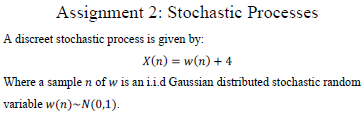

A normal gaussian distribution can be created using matlabs function normrnd()

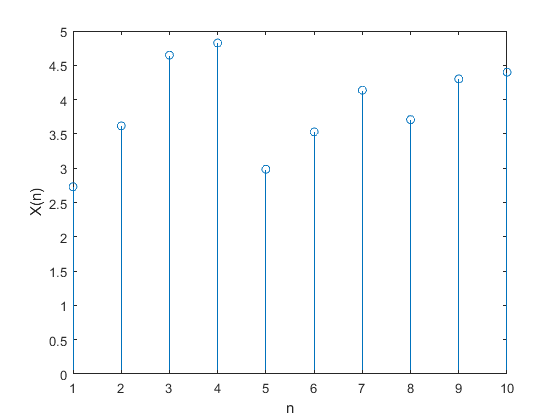

mu = 0;
sigma = 1;
n = 10;
wn = normrnd(mu,sigma,1,n);
X = wn + 4;
stem(X)
xlabel('n')
ylabel('X(n)')

The ensemble mean can be calculated using the formula for a standard normal distribution on pg. 52: $E\left\lbrack w\left(n\right)\right\rbrack =0$


$$E\left\lbrack X\right\rbrack =E\left\lbrack w\left(n\right)+4\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +E\left\lbrack 4\right\rbrack =0+4=4$$


ensemble_mean = 4;

The ensemble variance can be calculated using the formula for a standard normal distribution on pg. 52: $\mathrm{Var}\left(w\left(n\right)\right)=1$


$$\mathrm{Var}\left(X\right)=E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack +E\left\lbrack 4^2 \right\rbrack -4^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack =1$$


ensemble_var = 1;

The process is WSS, since the ensemble mean and variance are not dependent of time.

The process is ergodic since the mean and variance can be calculated from just one realization.

# SMP L7 - Forår 2016 assignment 2

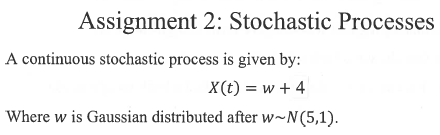

The random number generator randn() from matlab can be used.

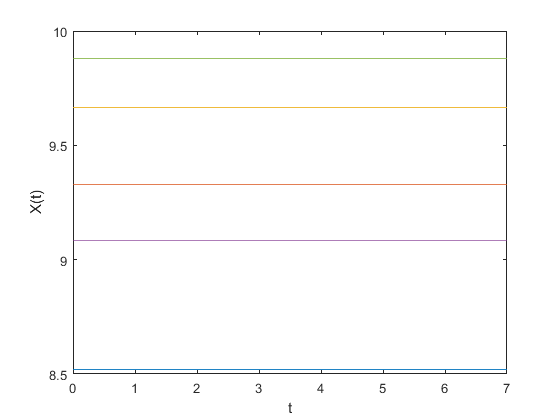

mu = 5;
sigma = 1;
n_realizations = 5;
wn = sigma*randn(1,n_realizations)+5;

X = wn + 4;

t = 0:7;
for i=1:n_realizations
    plot(t,X(i)*ones(1,length(t)))
    hold on
end
hold off
xlabel('t')
ylabel('X(t)')

The ensemble mean can be calculated using the formula for a normal distribution on pg. 53: $E\left\lbrack w\left(n\right)\right\rbrack =\mu$


$$E\left\lbrack X\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +E\left\lbrack 4\right\rbrack =5+4=9$$


ensemble_mean = 9;

The ensemble variance can be calculated using the formula for a normal distribution on pg. 53: $\mathrm{Var}\left(w\left(n\right)\right)=\sigma^2$


$$\mathrm{Var}\left(X\right)=E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack +E\left\lbrack 4^2 \right\rbrack -4^2 =E\left\lbrack {w\left(n\right)}^2 \right\rbrack =1^2 =1$$
 

ensemble_var = 1;

The temporal mean can be calculated using the equation from pg. 39 in the book: $\mu^ˆ =\frac{1}{N}\sum_{i=1}^N X_i$

The temporal variance can be calculated using the equation: $\hat{\sigma^2 } =\frac{1}{N-1}\sum_{i=1}^N {\left(X_i -\mu^ˆ \right)}^2$

Or using the matlab functions *mean* and *var*. Since each realization is a constant, the mean will be that value, and the variance will be 0.

% realization 1
temporal_mean = mean(X(1))

temporal_mean = 8.5191

temporal_var = var(X(1))

temporal_var = 0

The process is WSS, since the ensemble mean and variance are independt of time. 

However it is not ergodic because the temporal and ensemble mean are not identical. This can also be thought of as 1 realization does not contain all information about the process

# SMP L7 - Forår 2016 Reeksamen assignment 2

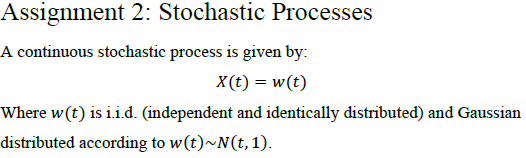

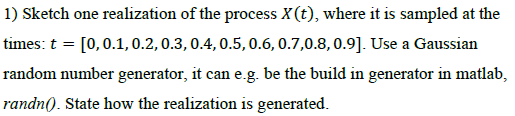

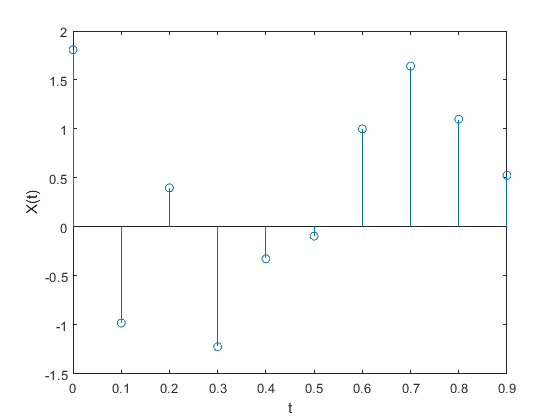

t = 0:0.1:0.9;
sigma = 1;
wt = sigma*randn(1,length(t))+t;
Xt = wt;

stem(t,Xt)
xlabel('t')
ylabel('X(t)')


$$E\left\lbrack X\left(t\right)\right\rbrack =E\left\lbrack w\left(t\right)\right\rbrack =t$$



$$\mathrm{Var}\left(X\left(t\right)\right)=\mathrm{Var}\left(w\left(t\right)\right)=1$$


I expect it to be 50 since it is the mean value of the time interval.


$$\mu^ˆ =\frac{1}{N}\int_{i=1}^N E\left\lbrack X\left(t\right)\right\rbrack \;\mathrm{dt}=\frac{1}{100}\sum_{i=1}^{100} t\;\mathrm{dt}=50$$


t1 = 0:100;
wt1 = sigma*randn(1,length(t1))+t1;
Xt1 = wt1;
mean(Xt1)

ans = 50.0937

The process is not WSS since the ensemble mean is dependent of time.

Since the process is not WSS it can not be ergodic either. 

Look at slide 14.


$$R_{\mathrm{XX}} \left(t_1 ,t_2 \right)=E\left\lbrack X\left(t_1 \right){X\left(t_2 \right)}^* \right\rbrack =\int \int_{-\infty }^{\infty } X\left(t_1 \right)X\left(t_2 \right)\cdot f_{X\left(t_1 \right),X\left(t_2 \right)} \left(x\left(t_1 \right),x\left(t_2 \right)\right)\;\mathrm{dx}\left(t_1 \right)\mathrm{dx}\left(t_2 \right)$$


Since the process is i.i.d we can calculate the autorcorrelation as (x1 and x2 are independent):


$$R_{X\left(t_1 \right)X\left(t_2 \right)} \left(t_1 =1,t_2 =2\right)=E\left\lbrack X\left(1\right)\right\rbrack \cdot E\left\lbrack X\left(2\right)\right\rbrack =1\cdot 2=2$$
